%rpiを削除
clear rpi 

%rpi接続設定
%家用
%rpi = raspi('192.168.0.53', 'pi', 'milkyway');
%大学用
rpi = raspi('10.24.77.202', 'pi', 'milkyway'); 

An active connection to 10.24.77.202 already exists. You cannot create another connection.

%電源LED(赤)の下のステータスLED(緑)をledとして定義
%led = rpi.AvailableLEDs{1};


cam = cameraboard(rpi);

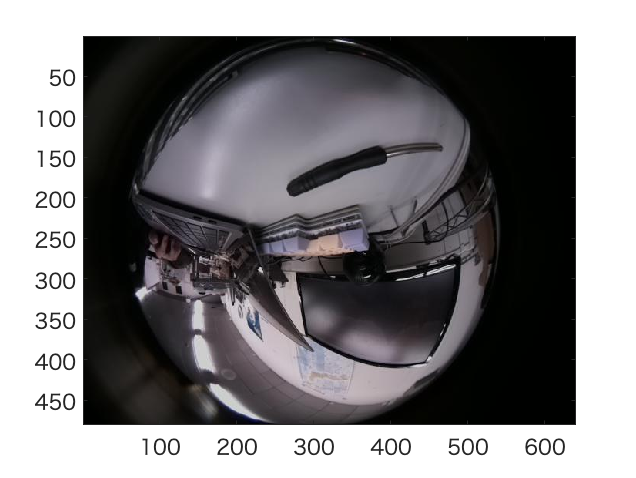

img = snapshot(cam);
imagesc(img);

Motion detected on 28-Oct-2022 17:46:23
Motion detected on 28-Oct-2022 17:46:29
Motion detected on 28-Oct-2022 17:46:37
Motion detected on 28-Oct-2022 17:46:43
Motion detected on 28-Oct-2022 17:46:49
Motion detected on 28-Oct-2022 17:46:58
Motion detected on 28-Oct-2022 17:47:06
Motion detected on 28-Oct-2022 17:47:11
Motion detected on 28-Oct-2022 17:47:19
Motion detected on 28-Oct-2022 17:47:25


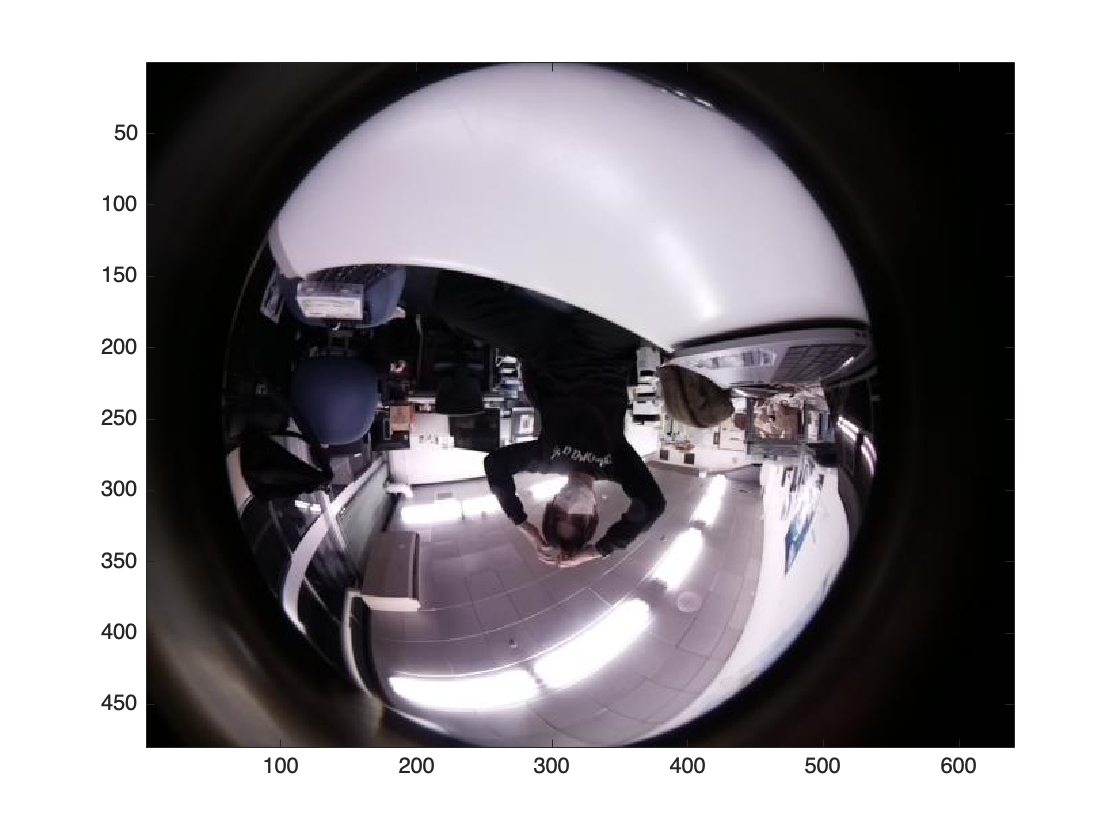

N = 100;
delay = 0.1;
frameNo = 0;
for i = 1:N
    motionDetected = readDigitalPin(rpi, 18);
    if motionDetected
       fprintf('Motion detected on %s\n', datestr(now));
       img = snapshot(cam);
       image(img);
       drawnow;
       imwrite(img, sprintf('image%d.jpg', frameNo));
       % Wait until the motion detector output goes low
       pause(5);
    end
    pause(delay);
end

%rpiを削除
clear rpi